## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Filtering**

## **Lab Session 2**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **(Dúvidas: filtro passa-baixo e equalizer)**

**%%REMINDER: enviar projeto com source files na pasta zipada**

# **1) 1D Filtering**

**1) **A função filtro(x,A,B), ao atuar num vetor x como um filtro linear, dá como output um vetor y : 

cada elemento de A(i) vai multiplicar pelo elemento do vetor x na posição n-i, sendo n a entrada atual que se está a calcular o vetor y. A isto soma-se adicionalmente cada elemento de B(j) a multiplicar pelo elemento do vetor y na posição n-j (portanto é necessário saber as saídas "passadas"). Obtém-se assim todas as entradas do vetor y.

**2) **

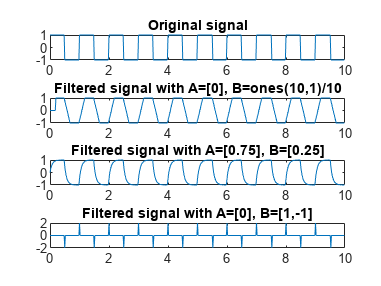

% Generate square wave
T = 10; % Total time
Tp = 1; % Period
fs = 50; % Sampling frequency
t = 0:1/fs:T-1/fs; % Time vector, 10-1/50 para ir até t=10s tops
x = square(2*pi/Tp*t); % Square wave signal

% Filter with coefficients A = [0], B = ones(10, 1)/10
A = [0];
B = ones(10, 1)/10;
y1 = filtro(x', A, B); % Filtered signal

% Filter with coefficients A = [0.75], B = [0.25]
A = [0.75];
B = [0.25];
y2 = filtro(x', A, B); % Filtered signal

% Filter with coefficients A = [0], B = [1, -1]
A = [0];
B = [1, -1];
y3 = filtro(x', A, B'); % Filtered signal

% Plot results
figure
subplot(4,1,1)
plot(t, x)
title('Original signal')
subplot(4,1,2)
plot(t, y1)
title('Filtered signal with A=[0], B=ones(10,1)/10')
subplot(4,1,3)
plot(t, y2)
title('Filtered signal with A=[0.75], B=[0.25]')
subplot(4,1,4)
plot(t, y3)
title('Filtered signal with A=[0], B=[1,-1]')

* comentar *

3) a)

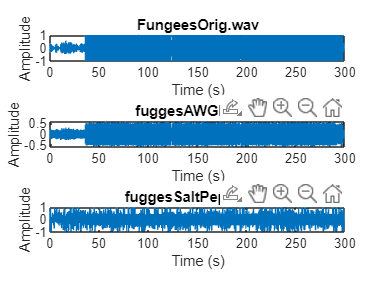

% Read the audio files
[x_awgn, fs_awgn] = audioread('fuggesAWGN.mp3');
[x_spn, fs_spn] = audioread('fuggesSaltPeper.mp3');
[x_orig, fs_orig] = audioread('FugeesOrig.mp3');

% Plot the audio signals
t_awgn = (0:length(x_awgn)-1)/fs_awgn;
t_spn = (0:length(x_spn)-1)/fs_spn;
t_orig = (0:length(x_orig)-1)/fs_orig;

figure;
subplot(3,1,1);
plot(t_orig, x_orig);
title('FungeesOrig.wav');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,2);
plot(t_awgn, x_awgn);
title('fuggesAWGN.wav');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,3);
plot(t_spn, x_spn);
title('fuggesSaltPeper.wav');
xlabel('Time (s)');
ylabel('Amplitude');

b)

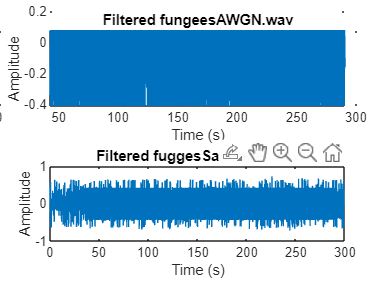

% Filter the audio signals using the linear low-pass filter
A = [0.75];
B = [0.25];
y_awgn = filtro(x_awgn', A, B);
y_spn = filtro(x_spn', A, B);

% Play and plot the filtered audio signals
sound(y_awgn, fs_awgn);
sound(y_spn, fs_spn);

figure;
subplot(2,1,1);
plot(t_awgn, y_awgn);
title('Filtered fungeesAWGN.wav');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(2,1,2);
plot(t_spn, y_spn);
title('Filtered fuggesSaltPeper.wav');
xlabel('Time (s)');
ylabel('Amplitude');

Os sinais de áudio resultantes mostram uma redução no ruído, especialmente no caso do sinal corrompido pelo SPN. No entanto, os sinais de saída ainda exibem alguns artefatos devido à resposta não ideal do filtro.

**c) **Save the sound vector in an audio file to be read in normal audio players

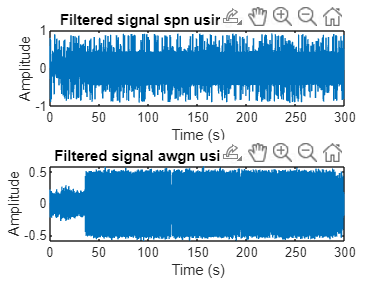

% Filter the signal using the median filter
N = 3;
y_med_awgn = medfilt1(x_awgn, N);
y_med_spn = medfilt1(x_spn, N);

% Play the filtered signal
sound(y_med_awgn, fs_awgn);
%%sound(y_med_spn, fs_spn);

% Plot the waveform of the filtered signal
figure;
subplot(2,1,1);
plot(t_spn, y_med_spn);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered signal spn using a median filter');
subplot(2,1,2);
plot(t_awgn, y_med_awgn);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered signal awgn using a median filter');

Comparando os resultados do filtro passa-baixo linear e do filtro mediana, podemos observar que o filtro mediana preserva melhor os transientes agudos do sinal do que o filtro linear, mas também introduz alguma distorção no sinal. No entanto, o filtro linear remove o ruído de alta frequência de forma mais eficaz e produz um sinal de saída mais suave.

d)

Em relação aos resultados obtidos com a filtragem dos sinais de áudio com o filtro linear passa-baixo e o filtro mediano, podemos fazer os seguintes comentários:

O sinal de áudio filtrado usando o filtro passa-baixo linear é mais suave e reduz o ruído de alta frequência em comparação com o sinal original. O filtro passa-baixo atenua os componentes de alta frequência do sinal, que normalmente estão associados ao ruído, e passa os componentes de baixa frequência do sinal. Como resultado, o sinal de áudio filtrado é mais limpo e agradável de ouvir. No entanto, o filtro também suaviza algumas das características transitórias do sinal, que podem ser indesejáveis se forem importantes para a percepção ou análise da música;

O sinal de áudio filtrado usando o filtro mediana preservou os transientes agudos do sinal melhor do que o filtro linear, mas também introduziu alguma distorção no sinal. O filtro mediana substitui cada amostra no sinal pela mediana de suas amostras vizinhas, o que pode efetivamente remover os picos ou impulsos no sinal causados pelo ruído. No entanto, o filtro também produz alguma distorção no sinal porque é não linear e modifica a forma da forma de onda. A distorção pode ser audível e afetar a qualidade da música.

No geral, a escolha do filtro depende dos requisitos específicos da aplicação e do compromisso entre redução de ruído e distorção do sinal. Se preservar as características transitórias do sinal for importante, o filtro mediano pode ser o preferido. Se reduzir o ruído e suavizar o sinal for a prioridade, o filtro passa-baixo linear pode ser mais adequado.

# **2) **